# **Assignment 1: Tyre fitting**

**Team 6: Consalvi Natale, Pettene Mattia, Zumerle Matteo**

*Last update: 23/04 h.23.30 ~N*

### Initialisation

clc
clearvars 
close all   

% Set LaTeX as default interpreter for axis labels, ticks and legends
set(0,'defaulttextinterpreter','latex')
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

set(0,'DefaultFigureWindowStyle','docked');
set(0,'defaultAxesFontSize',  16)
set(0,'DefaultLegendFontSize',16)

% Add path
addpath('tyre_lib/');

to_rad = pi/180;
to_deg = 180/pi;

# **Pure longitudinal force**

### **Tyre dataset selection and loading**

%dataset path
data_set_path = 'dataset/';
% dataset selection and loading

%data_set = 'Hoosier_B1464run23'; % pure lateral forces
data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined

% tyre geometric data:
% Hoosier	18.0x6.0-10
% 18 diameter in inches
% 6.0 section width in inches
% tread width in inches
diameter = 18*2.56; %
Fz0 = 220;   % [N] nominal load is given
R0  = diameter/2/100; % [m] get from nominal load R0 (m) *** TO BE CHANGED ***


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'Hoosier_B1464run23'
  load ([data_set_path, 'Hoosier_B1464run23.mat']); % pure lateral
  cut_start = 27760;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range = cut_start:cut_end;

fprintf('completed!\n')

completed!


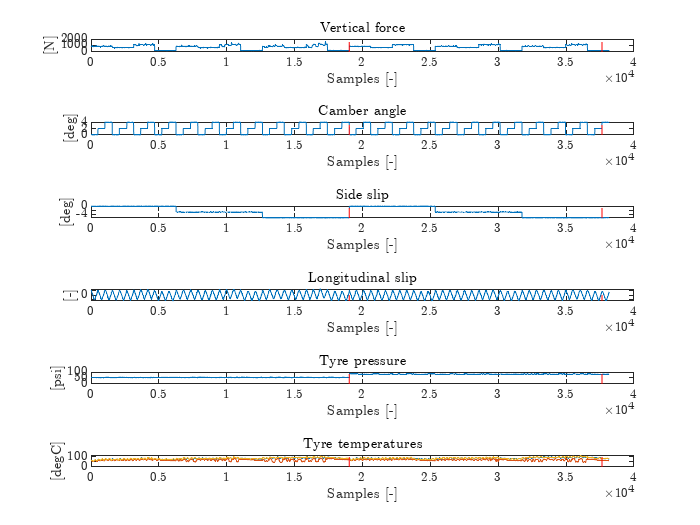

%% Plot raw data

figure
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[psi]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list,'x')

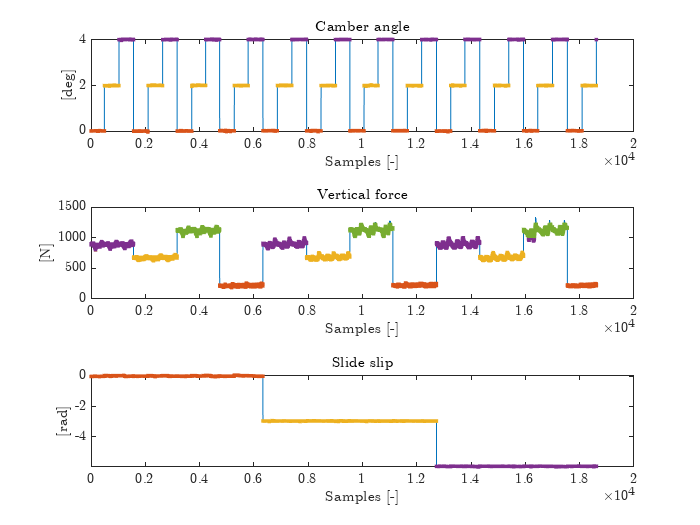



%plot(SA,FY)


%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples = 1:1:length(smpl_range);
tyre_data = table(); % create empty table
% store raw data in table
tyre_data.SL =  SL(smpl_range);
tyre_data.SA =  SA(smpl_range)*to_rad;
tyre_data.FZ = -FZ(smpl_range);  % 0.453592  lb/kg
tyre_data.FX =  FX(smpl_range);
tyre_data.FY =  FY(smpl_range);
tyre_data.MZ =  MZ(smpl_range);
tyre_data.IA =  IA(smpl_range)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 0.0*to_rad+GAMMA_tol;
idx.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 1.0*to_rad+GAMMA_tol;
idx.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 2.0*to_rad+GAMMA_tol;
idx.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 3.0*to_rad+GAMMA_tol;
idx.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 4.0*to_rad+GAMMA_tol;
idx.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0  = tyre_data( idx.GAMMA_0, : );
GAMMA_1  = tyre_data( idx.GAMMA_1, : );
GAMMA_2  = tyre_data( idx.GAMMA_2, : );
GAMMA_3  = tyre_data( idx.GAMMA_3, : );
GAMMA_4  = tyre_data( idx.GAMMA_4, : );
GAMMA_5  = tyre_data( idx.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx.FZ_220  = 220-FZ_tol < tyre_data.FZ & tyre_data.FZ < 220+FZ_tol;
idx.FZ_440  = 440-FZ_tol < tyre_data.FZ & tyre_data.FZ < 440+FZ_tol;
idx.FZ_700  = 700-FZ_tol < tyre_data.FZ & tyre_data.FZ < 700+FZ_tol;
idx.FZ_900  = 900-FZ_tol < tyre_data.FZ & tyre_data.FZ < 900+FZ_tol;
idx.FZ_1120 = 1120-FZ_tol < tyre_data.FZ & tyre_data.FZ < 1120+FZ_tol;
FZ_220  = tyre_data( idx.FZ_220, : );
FZ_440  = tyre_data( idx.FZ_440, : );
FZ_700  = tyre_data( idx.FZ_700, : );
FZ_900  = tyre_data( idx.FZ_900, : );
FZ_1120 = tyre_data( idx.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

% The slip angle is varied step wise for longitudinal slip tests
% 0° , - 3° , -6 °
SA_tol = 0.5*to_rad;
idx.SA_0    =  0-SA_tol          < tyre_data.SA & tyre_data.SA < 0+SA_tol;
idx.SA_3neg = -(3*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -3*to_rad+SA_tol;
idx.SA_6neg = -(6*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -6*to_rad+SA_tol;
SA_0     = tyre_data( idx.SA_0, : );
SA_3neg  = tyre_data( idx.SA_3neg, : );
SA_6neg  = tyre_data( idx.SA_6neg, : );

figure()
tiledlayout(3,1)

ax_list(1) = nexttile;
plot(tyre_data.IA*to_deg)
hold on
plot(vec_samples(idx.GAMMA_0),GAMMA_0.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_1),GAMMA_1.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_2),GAMMA_2.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_3),GAMMA_3.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_4),GAMMA_4.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_5),GAMMA_5.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data.FZ)
hold on
plot(vec_samples(idx.FZ_220),FZ_220.FZ,'.');
plot(vec_samples(idx.FZ_440),FZ_440.FZ,'.');
plot(vec_samples(idx.FZ_700),FZ_700.FZ,'.');
plot(vec_samples(idx.FZ_900),FZ_900.FZ,'.');
plot(vec_samples(idx.FZ_1120),FZ_1120.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')


ax_list(3) = nexttile;
plot(tyre_data.SA*to_deg)
hold on
plot(vec_samples(idx.SA_0),   SA_0.SA*to_deg,'.');
plot(vec_samples(idx.SA_3neg),SA_3neg.SA*to_deg,'.');
plot(vec_samples(idx.SA_6neg),SA_6neg.SA*to_deg,'.');
title('Slide slip')
xlabel('Samples [-]')
ylabel('[rad]')

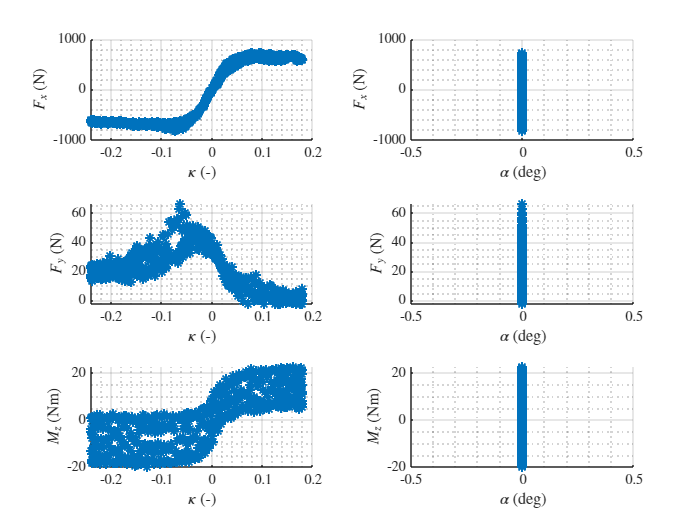





%% Intersect tables to obtain specific sub-datasets

[TData0, ~] = intersect_table_data( SA_0, GAMMA_0, FZ_220 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')
plot_selected_data(TData0);

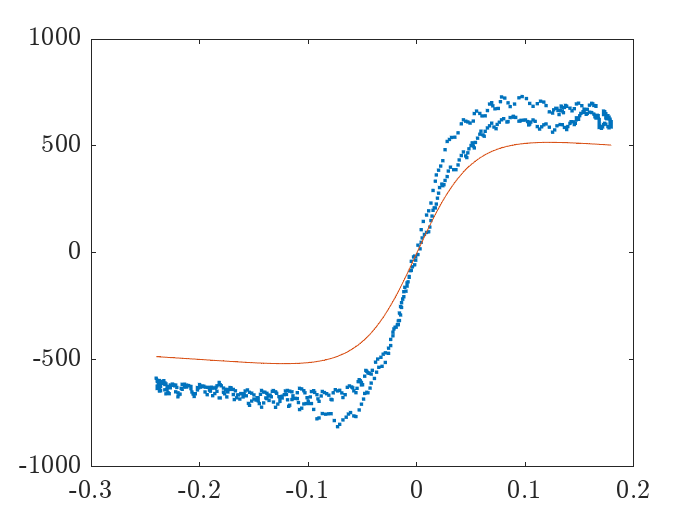


%% FITTING 
% initialise tyre data
tyre_coeffs = initialise_tyre_data(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0  alpha = 0 VX= 10
% ------------------
% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TData0.SL));
ones_vec  = ones(size(TData0.SL));

FX0_guess = MF96_FX0_vec(TData0.SL,zeros_vec , zeros_vec, tyre_coeffs.FZ0*ones_vec, tyre_coeffs);

% check guess 
figure()
plot(TData0.SL,TData0.FX,'.')
hold on
plot(TData0.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
P0 = [  1,   2,   1,  0,   0,   1,   0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [1,   0.1,   0,   0,  -10,    0,   -10];
ub = [2,    4,   1,   1,   10,   100,  10];


KAPPA_vec = TData0.SL;
FX_vec    = TData0.FX;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Fx(P,FX_vec, KAPPA_vec,0,FZ0, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


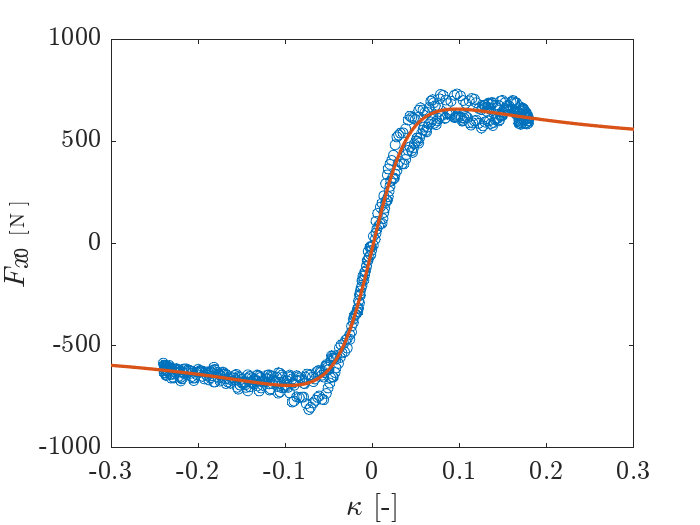


% Update tyre data with new optimal values                             
tyre_coeffs.pCx1 = P_fz_nom(1) ; % 1
tyre_coeffs.pDx1 = P_fz_nom(2) ;  
tyre_coeffs.pEx1 = P_fz_nom(3) ;
tyre_coeffs.pEx4 = P_fz_nom(4) ;
tyre_coeffs.pHx1 = P_fz_nom(5) ; 
tyre_coeffs.pKx1 = P_fz_nom(6) ;
tyre_coeffs.pVx1 = P_fz_nom(7) ;

FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs);

figure('Name','Fx0(Fz0)')
plot(TData0.SL,TData0.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,FX0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

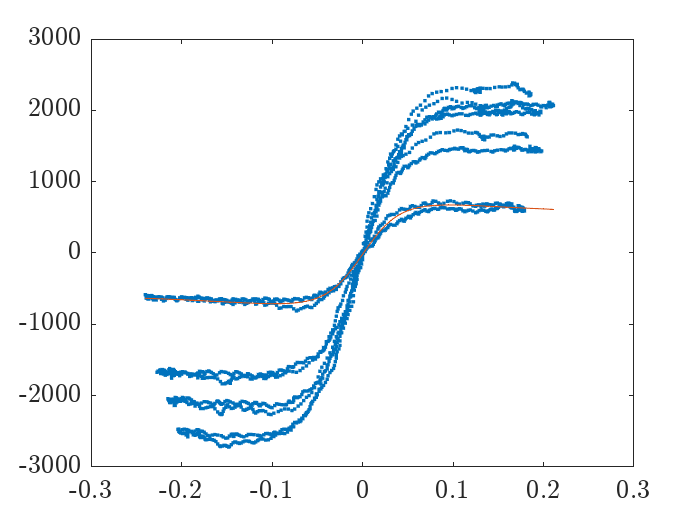


%% Fit coeefficient with variable load
% extract data with variable load
[TDataDFz, ~] = intersect_table_data( SA_0, GAMMA_0 );

% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz.SL));
ones_vec  = ones(size(TDataDFz.SL));

FX0_guess = MF96_FX0_vec(TDataDFz.SL,zeros_vec , zeros_vec, tyre_coeffs.FZ0*ones_vec, tyre_coeffs);

% check guess 
figure()
plot(TDataDFz.SL,TDataDFz.FX,'.')
hold on
plot(TDataDFz.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pDx2 pEx2 pEx3 pHx2  pKx2  pKx3  pVx2] 
P0 = [  0,   0,   0,  0,   0,   0,   0]; 


% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [];
ub = [];


KAPPA_vec = TDataDFz.SL;
FX_vec    = TDataDFz.FX;
FZ_vec    = TDataDFz.FZ;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_dfz_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                           TDataDFz.FZ,tyre_coeffs);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_dfz_vec,'.')


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varFz(P,FX_vec, KAPPA_vec,0,FZ_vec, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



disp(exitflag)

     1



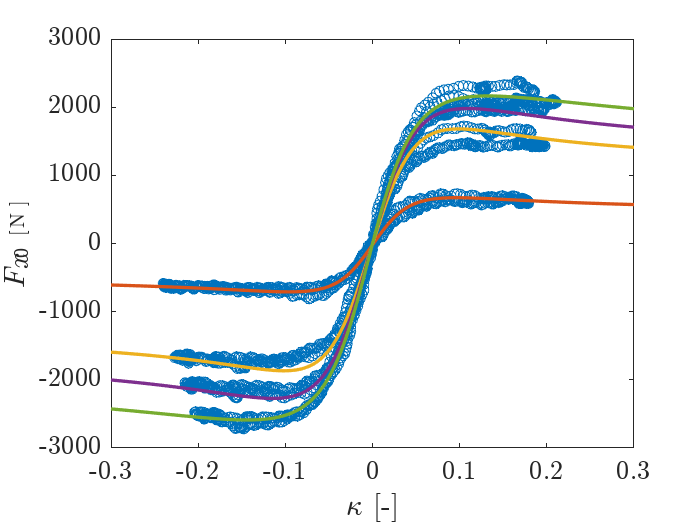

% Change tyre data with new optimal values                             
tyre_coeffs.pDx2 = P_dfz(1) ; % 1
tyre_coeffs.pEx2 = P_dfz(2) ;  
tyre_coeffs.pEx3 = P_dfz(3) ;
tyre_coeffs.pHx2 = P_dfz(4) ;
tyre_coeffs.pKx2 = P_dfz(5) ; 
tyre_coeffs.pKx3 = P_dfz(6) ;
tyre_coeffs.pVx2 = P_dfz(7) ;


res_FX0_dfz_vec = resid_pure_Fx_varFz(P_dfz,FX_vec,SL_vec,0 , FZ_vec,tyre_coeffs);

tmp_zeros = zeros(size(SL_vec));
tmp_ones = ones(size(SL_vec));


FX0_fz_var_vec1 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec2 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec3 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec4 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);


figure('Name','Fx0(Fz0)')
plot(TDataDFz.SL,TDataDFz.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec1,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec2,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec3,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec4,'-','LineWidth',2)

xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

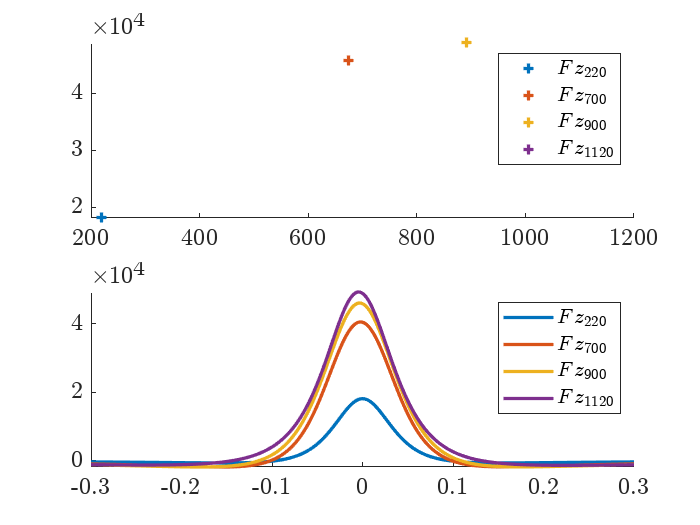



[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_220.FZ), tyre_coeffs);
Calfa_vec1_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_700.FZ), tyre_coeffs);
Calfa_vec2_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_900.FZ), tyre_coeffs);
Calfa_vec3_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_1120.FZ), tyre_coeffs);
Calfa_vec4_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);

Calfa_vec1 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec2 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec3 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec4 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);

figure('Name','C_alpha')
subplot(2,1,1)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(mean(FZ_220.FZ),Calfa_vec1_0,'+','LineWidth',2)
plot(mean(FZ_700.FZ),Calfa_vec3_0,'+','LineWidth',2)
plot(mean(FZ_900.FZ),Calfa_vec4_0,'+','LineWidth',2)
plot(mean(FZ_1120.FZ),Calfa_vec2_0,'+','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

subplot(2,1,2)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,Calfa_vec1,'-','LineWidth',2)
plot(SL_vec,Calfa_vec2,'-','LineWidth',2)
plot(SL_vec,Calfa_vec3,'-','LineWidth',2)
plot(SL_vec,Calfa_vec4,'-','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

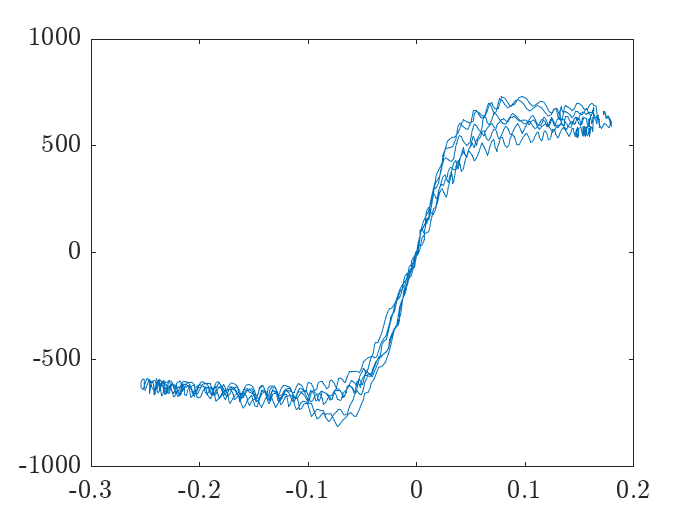



%% Fit coefficient with variable camber

% extract data with variable load
[TDataGamma, ~] = intersect_table_data( SA_0, FZ_220 );

% Fit the coeffs { pDx3}

% Guess values for parameters to be optimised
P0 = [0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%lb = [0, 0,  0, 0,  0,  0,  0];
%ub = [2, 1e6,1, 1,1e1,1e2,1e2];
lb = [];
ub = [];


zeros_vec = zeros(size(TDataGamma.SL));
ones_vec  = ones(size(TDataGamma.SL));

KAPPA_vec = TDataGamma.SL;
GAMMA_vec = TDataGamma.IA; 
FX_vec    = TDataGamma.FX;
FZ_vec    = TDataGamma.FZ;

figure()
plot(KAPPA_vec,FX_vec);



% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 
[P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varGamma(P,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


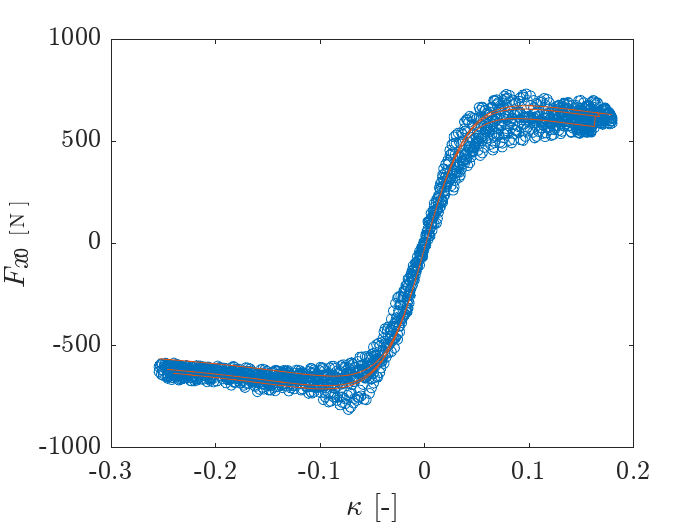


% Change tyre data with new optimal values                             
tyre_coeffs.pDx3 = P_varGamma(1) ; % 1

FX0_varGamma_vec = MF96_FX0_vec(KAPPA_vec,zeros_vec , GAMMA_vec, tyre_coeffs.FZ0*ones_vec,tyre_coeffs);

figure('Name','Fx0 vs Gamma')
plot(KAPPA_vec,TDataGamma.FX,'o')
hold on
plot(KAPPA_vec,FX0_varGamma_vec,'-')
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

% Calculate the residuals with the optimal solution found above
res_Fx0_varGamma  = resid_pure_Fx_varGamma(P_varGamma,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs);

% R-squared is 
% 1-SSE/SST
% SSE/SST = res_Fx0_nom

% SSE is the sum of squared error,  SST is the sum of squared total
fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);

R-squared =  0.994




[kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs.FZ0, tyre_coeffs);
% 
fprintf('Bx      = %6.3f\n',Bx);

Bx      = 17.021


fprintf('Cx      = %6.3f\n',Cx);

Cx      =  1.539


fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);

mux      =  3.147


fprintf('Ex      = %6.3f\n',Ex);

Ex      =  0.011


fprintf('SVx     = %6.3f\n',SVx);

SVx     = -18.871


fprintf('kappa_x = %6.3f\n',kappa__x);

kappa_x = -0.000


fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);

Kx      = 82.417



% % Longitudinal stiffness
% Kx_vec = zeros(size(load_vec));
% for i = 1:length(load_vec)
%   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
%   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% end
% 
% figure('Name','Kx vs Fz')
% plot(load_vec,Kx_vec,'o-')

%% Save tyre data structure to mat file
%
save(['tyre_' data_set,'.mat'],'tyre_coeffs');


# **Pure lateral force**

data_set = 'Hoosier_B1464run23'; % pure lateral forces
%data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'Hoosier_B1464run23'
  load ([data_set_path, 'Hoosier_B1464run23.mat']); % pure lateral
  cut_start = 31286;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range_pl = cut_start:cut_end;

fprintf('completed!\n')

completed!


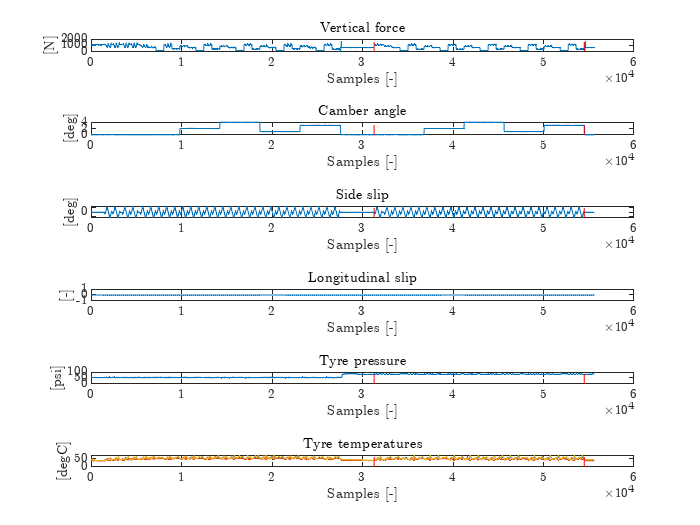

% Plot raw data

figure
tiledlayout(6,1)

ax_list_pl(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list_pl(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_pl(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_pl(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list_pl(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[psi]')

ax_list_pl(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list_pl,'x')

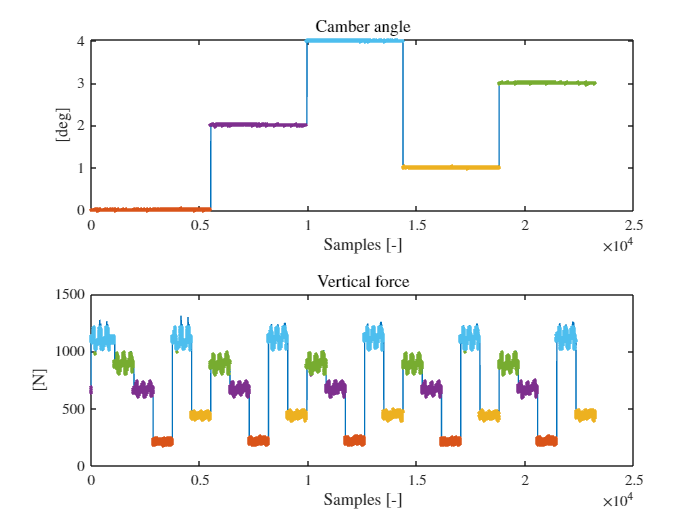

%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples_pl = 1:1:length(smpl_range_pl);
tyre_data_pl = table(); % create empty table
% store raw data in table
tyre_data_pl.SL =  SL(smpl_range_pl);
tyre_data_pl.SA = -SA(smpl_range_pl)*to_rad;
tyre_data_pl.FZ = -FZ(smpl_range_pl);  % 0.453592  lb/kg
tyre_data_pl.FX =  FX(smpl_range_pl);
tyre_data_pl.FY =  FY(smpl_range_pl);
tyre_data_pl.MZ =  MZ(smpl_range_pl);
tyre_data_pl.IA =  IA(smpl_range_pl)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx_pl.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 0.0*to_rad+GAMMA_tol;
idx_pl.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 1.0*to_rad+GAMMA_tol;
idx_pl.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 2.0*to_rad+GAMMA_tol;
idx_pl.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 3.0*to_rad+GAMMA_tol;
idx_pl.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 4.0*to_rad+GAMMA_tol;
idx_pl.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data_pl.IA & tyre_data_pl.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0_pl  = tyre_data_pl( idx_pl.GAMMA_0, : );
GAMMA_1_pl  = tyre_data_pl( idx_pl.GAMMA_1, : );
GAMMA_2_pl  = tyre_data_pl( idx_pl.GAMMA_2, : );
GAMMA_3_pl  = tyre_data_pl( idx_pl.GAMMA_3, : );
GAMMA_4_pl  = tyre_data_pl( idx_pl.GAMMA_4, : );
GAMMA_5_pl  = tyre_data_pl( idx_pl.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 100lbf (100*0.453592*9.81 =  445N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx_pl.FZ_220  = 220-FZ_tol < tyre_data_pl.FZ & tyre_data_pl.FZ < 220+FZ_tol;
idx_pl.FZ_440  = 440-FZ_tol < tyre_data_pl.FZ & tyre_data_pl.FZ < 440+FZ_tol;
idx_pl.FZ_700  = 700-FZ_tol < tyre_data_pl.FZ & tyre_data_pl.FZ < 700+FZ_tol;
idx_pl.FZ_900  = 900-FZ_tol < tyre_data_pl.FZ & tyre_data_pl.FZ < 900+FZ_tol;
idx_pl.FZ_1120 = 1120-FZ_tol < tyre_data_pl.FZ & tyre_data_pl.FZ < 1120+FZ_tol;
FZ_220_pl  = tyre_data_pl( idx_pl.FZ_220, : );
FZ_440_pl  = tyre_data_pl( idx_pl.FZ_440, : );
FZ_700_pl  = tyre_data_pl( idx_pl.FZ_700, : );
FZ_900_pl  = tyre_data_pl( idx_pl.FZ_900, : );
FZ_1120_pl = tyre_data_pl( idx_pl.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

% % The slip angle is varied step wise for longitudinal slip tests
% % 0° , - 3° , -6 °
% SA_tol = 0.5*to_rad;
% idx_pl.SA_0    =  0-SA_tol          < tyre_data_pl.SA & tyre_data_pl.SA < 0+SA_tol;
% idx_pl.SA_3neg = -(3*to_rad+SA_tol) < tyre_data_pl.SA & tyre_data_pl.SA < -3*to_rad+SA_tol;
% idx_pl.SA_6neg = -(6*to_rad+SA_tol) < tyre_data_pl.SA & tyre_data_pl.SA < -6*to_rad+SA_tol;
% SA_0_pl     = tyre_data_pl( idx_pl.SA_0, : );
% SA_3neg_pl  = tyre_data_pl( idx_pl.SA_3neg, : );
% SA_6neg_pl  = tyre_data_pl( idx_pl.SA_6neg, : );

figure()
tiledlayout(2,1)

ax_list(1) = nexttile;
plot(tyre_data_pl.IA*to_deg)
hold on
plot(vec_samples_pl(idx_pl.GAMMA_0),GAMMA_0_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_1),GAMMA_1_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_2),GAMMA_2_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_3),GAMMA_3_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_4),GAMMA_4_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_5),GAMMA_5_pl.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data_pl.FZ)
hold on
plot(vec_samples_pl(idx_pl.FZ_220),FZ_220_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_440),FZ_440_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_700),FZ_700_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_900),FZ_900_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_1120),FZ_1120_pl.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

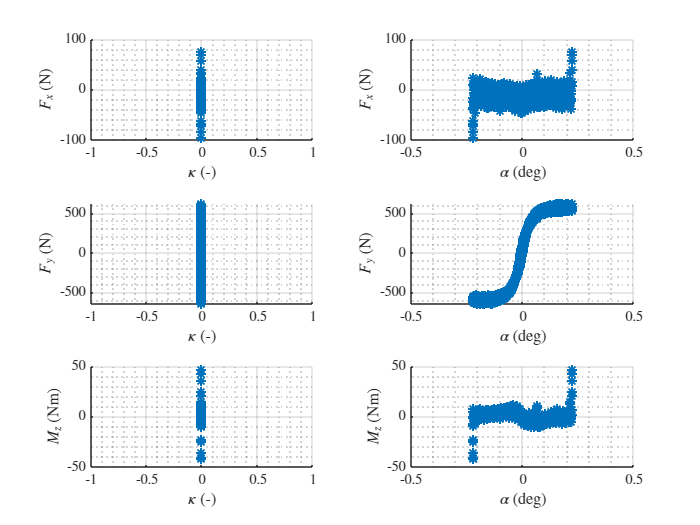

%% Intersect tables to obtain specific sub-datasets

[TData0_pl, ~] = intersect_table_data(GAMMA_0_pl, FZ_220_pl );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')
plot_selected_data(TData0_pl);

%% FITTING 
% initialise tyre data
tyre_coeffs_pl = initialise_tyre_data_ply(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0 
% ------------------
% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
FZ0 = mean(TData0_pl.FZ);

zeros_vec_pl = zeros(size(TData0_pl.SL));
ones_vec_pl  = ones(size(TData0_pl.SL));

prova = MF96_FY0(0, TData0_pl.SA(1), 0, FZ0, tyre_coeffs_pl)

prova = -28.1373

[prova_alpha__y, prova_By, prova_Cy, prova_Dy, prova_Ey, prova_SVy, prova_Kya, prova_SHy, prova_mu__y] = MF96_FY0_coeffs(0, TData0_pl.SA(1), 0, FZ0, tyre_coeffs_pl)

prova_alpha__y = -0.0059

prova_By = 8.0470

prova_Cy = 1.5403

prova_Dy = 526.5115

prova_Ey = 0.3462

prova_SVy = 10.3127

prova_Kya = 6.5259e+03

prova_SHy = -0.0049

prova_mu__y = 2.4340

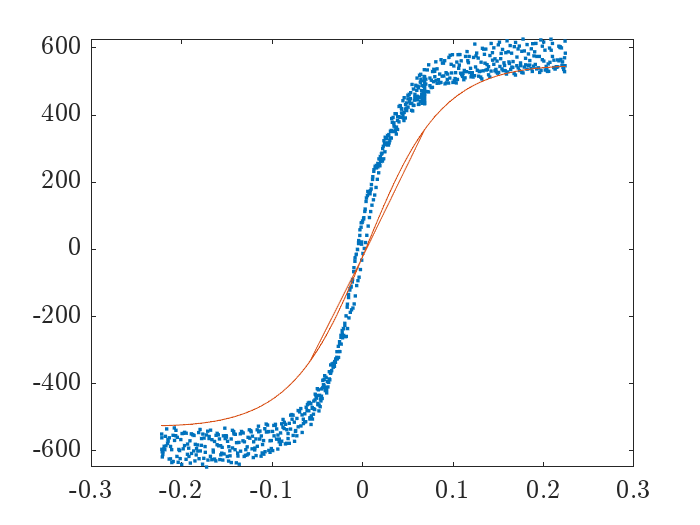


FY0_guess = MF96_FY0_vec(zeros_vec_pl, TData0_pl.SA , zeros_vec_pl, tyre_coeffs_pl.FZ0*ones_vec_pl, tyre_coeffs_pl);



% check guess 
figure()
plot(TData0_pl.SA,TData0_pl.FY,'.')
hold on
plot(TData0_pl.SA,FY0_guess,'-')

% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1 
P0_pl = [  1.5,   2.43,   0.34,  -0.48e-2,   -0.29e2,   -0.10e1,   0.47e-1]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1
%lb = [1,   0.1,   0,   0,  -10,    0,   -10];
%ub = [2,    4,   1,   1,   10,   100,  10];


ALPHA_vec = TData0_pl.SA;
FY_vec    = TData0_pl.FY;

% check guess
SA_vec = -12*to_rad:0.001:12*to_rad;
FY0_fz_nom_vec = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_pl);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Fy(P,FY_vec, ALPHA_vec,0,FZ0, tyre_coeffs_pl),...
                               P0_pl,[],[],[],[],[],[]); %ultimi 2 lb, ub)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



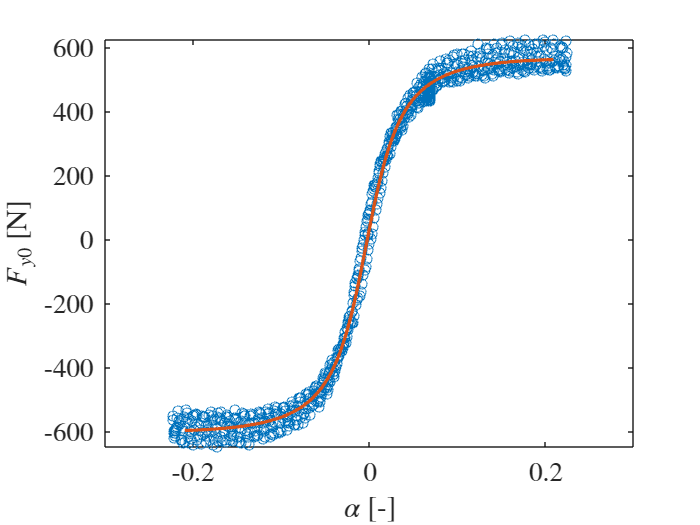


% Update tyre data with new optimal values                                        
tyre_coeffs_pl.pCy1 = P_fz_nom(1) ; % 1
tyre_coeffs_pl.pDy1 = P_fz_nom(2) ;  
tyre_coeffs_pl.pEy1 = P_fz_nom(3) ;
tyre_coeffs_pl.pHy1 = P_fz_nom(4) ;
tyre_coeffs_pl.pKy1 = P_fz_nom(5) ; 
tyre_coeffs_pl.pKy2 = P_fz_nom(6) ;
tyre_coeffs_pl.pVy1 = P_fz_nom(7) ;

FY0_fz_nom_vec = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_pl);

figure('Name','Fy0(Fz0)')
plot(TData0_pl.SA,TData0_pl.FY,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SA_vec,FY0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\alpha$ [-]')
ylabel('$F_{y0}$ [N]')

%% Fit coeefficient with variable load
% extract data with variable load
TDataDFz_pl= GAMMA_0_pl;

Unrecognized function or variable 'SL_0'.


% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz_pl.SA));
ones_vec  = ones(size(TDataDFz_pl.SA));

FY0_guess_dFz = MF96_FY0_vec( zeros_vec, TDataDFz_pl.SA, zeros_vec , tyre_coeffs_pl.FZ0*ones_vec, tyre_coeffs_pl);

% check guess 
figure()
plot(TDataDFz_pl.SA,TDataDFz_pl.FY,'.')
hold on
plot(TDataDFz_pl.SA,FY0_guess_dFz,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pDy2 pEy2 pHy2 pVy2] 
pDy2 =0;
pEy2 =0;
pHy2 =0;
pVy2 =0;

P0_pl_dFz = [pDy2, pEy2, pHy2 pVy2]; 


% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pDy2 pEy2 pHy2 pVy2
lb_dFz = [-5, -30, -5, -5];
ub_dFz = [10, -10, 0, 0];


ALPHA_vec_dFz = TDataDFz_pl.SA;
FY_vec_dFz    = TDataDFz_pl.FX;
FZ_vec_dFz    = TDataDFz_pl.FZ;

% check guess
%SL_vec = -0.3:0.001:0.3;
FY0_dfz_vec = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ_vec_dFz,tyre_coeffs_pl);

% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SA_vec,FY0_dfz_vec,'.')

% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz_pl,fval,exitflag] = fmincon(@(P)resid_pure_Fy_varFz(P,FY_vec_dFz, ALPHA_vec_dFz,0,FZ_vec_dFz, tyre_coeffs_pl),...
                               P0_pl_dFz,[],[],[],[],lb_dFz,ub_dFz);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


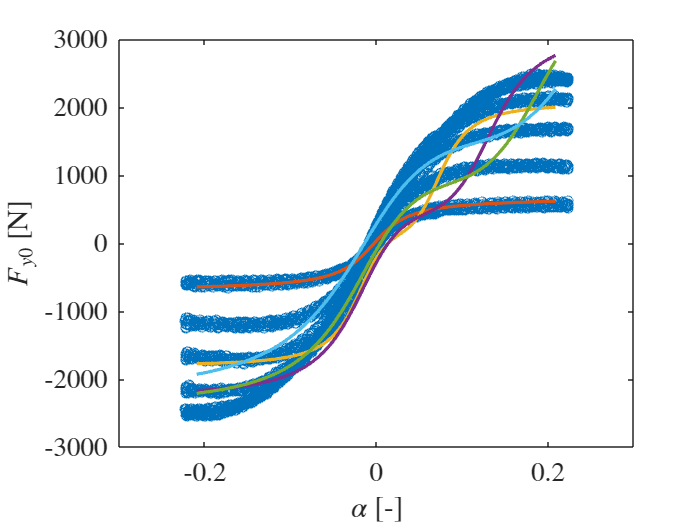


% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDy2 = P_dfz_pl(1) ; % 1
tyre_coeffs_pl.pEy2 = P_dfz_pl(2) ;  
tyre_coeffs_pl.pHy2 = P_dfz_pl(3) ;
tyre_coeffs_pl.pVy2 = P_dfz_pl(4) ;
   

res_FY0_dfz_vec = resid_pure_Fy_varFz(P_dfz_pl,FY_vec_dFz,SA_vec,0 , FZ_vec_dFz,tyre_coeffs_pl);

tmp_zeros_pl = zeros(size(SA_vec));
tmp_ones = ones(size(SA_vec));

FY0_fz_var_vec1 = MF96_FY0_vec(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_220_pl.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec2 = MF96_FY0_vec(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_440_pl.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec3 = MF96_FY0_vec(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_700_pl.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec4 = MF96_FY0_vec(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_900_pl.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec5 = MF96_FY0_vec(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_1120_pl.FZ)*tmp_ones,tyre_coeffs_pl);


figure('Name','Fy0(Fz0)')
plot(TDataDFz_pl.SA,TDataDFz_pl.FY,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SA_vec,FY0_fz_var_vec1,'-','LineWidth',2)
plot(SA_vec,FY0_fz_var_vec2,'-','LineWidth',2)
plot(SA_vec,FY0_fz_var_vec3,'-','LineWidth',2)
plot(SA_vec,FY0_fz_var_vec4,'-','LineWidth',2)
plot(SA_vec,FY0_fz_var_vec5,'-','LineWidth',2)

xlabel('$\alpha$ [-]')
ylabel('$F_{y0}$ [N]')

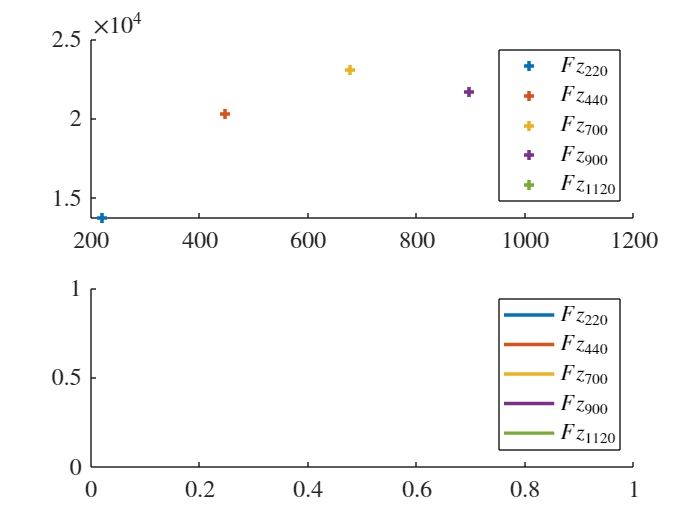



[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_220_pl.FZ), tyre_coeffs_pl);
Calfa_vec1_0_pl = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_440_pl.FZ), tyre_coeffs_pl);
Calfa_vec2_0_pl = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_700_pl.FZ), tyre_coeffs_pl);
Calfa_vec3_0_pl = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_900_pl.FZ), tyre_coeffs_pl);
Calfa_vec4_0_pl = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_1120_pl.FZ), tyre_coeffs_pl);
Calfa_vec5_0_pl = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);

Calfa_vec1_pl = MF96_CorneringStiffness(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_220_pl.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec2_pl = MF96_CorneringStiffness(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_440_pl.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec3_pl = MF96_CorneringStiffness(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_700_pl.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec4_pl = MF96_CorneringStiffness(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_900_pl.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec5_pl = MF96_CorneringStiffness(tmp_zeros_pl, SA_vec ,tmp_zeros_pl, mean(FZ_1120_pl.FZ)*tmp_ones,tyre_coeffs_pl);

figure('Name','C_alpha')
subplot(2,1,1)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(mean(FZ_220_pl.FZ),Calfa_vec1_0_pl,'+','LineWidth',2)
plot(mean(FZ_440_pl.FZ),Calfa_vec2_0_pl,'+','LineWidth',2)
plot(mean(FZ_700_pl.FZ),Calfa_vec3_0_pl,'+','LineWidth',2)
plot(mean(FZ_900_pl.FZ),Calfa_vec4_0_pl,'+','LineWidth',2)
plot(mean(FZ_1120_pl.FZ),Calfa_vec5_0_pl,'+','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{440}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

subplot(2,1,2)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SA_vec,Calfa_vec1_pl,'-','LineWidth',2)
plot(SA_vec,Calfa_vec2_pl,'-','LineWidth',2)
plot(SA_vec,Calfa_vec3_pl,'-','LineWidth',2)
plot(SA_vec,Calfa_vec4_pl,'-','LineWidth',2)
plot(SA_vec,Calfa_vec5_pl,'-','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{440}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})



% %% Fit coefficient with variable camber
% 
% % extract data with variable load
% [TDataGamma, ~] = intersect_table_data( SA_0, FZ_220 );
% 
% % Fit the coeffs { pDx3}
% 
% % Guess values for parameters to be optimised
% P0 = [0]; 
% 
% % NOTE: many local minima => limits on parameters are fundamentals
% % Limits for parameters to be optimised
% % 1< pCx1 < 2 
% % 0< pEx1 < 1 
% %lb = [0, 0,  0, 0,  0,  0,  0];
% %ub = [2, 1e6,1, 1,1e1,1e2,1e2];
% lb = [];
% ub = [];
% 
% 
% zeros_vec = zeros(size(TDataGamma.SL));
% ones_vec  = ones(size(TDataGamma.SL));
% 
% KAPPA_vec = TDataGamma.SL;
% GAMMA_vec = TDataGamma.IA; 
% FX_vec    = TDataGamma.FX;
% FZ_vec    = TDataGamma.FZ;
% 
% figure()
% plot(KAPPA_vec,FX_vec);
% 
% 
% % LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% % is an unconstrained minimization problem 
% [P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varGamma(P,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs),...
%                                P0,[],[],[],[],lb,ub);
% 
% % Change tyre data with new optimal values                             
% tyre_coeffs.pDx3 = P_varGamma(1) ; % 1
% 
% FX0_varGamma_vec = MF96_FX0_vec(KAPPA_vec,zeros_vec , GAMMA_vec, tyre_coeffs.FZ0*ones_vec,tyre_coeffs);
% 
% figure('Name','Fx0 vs Gamma')
% plot(KAPPA_vec,TDataGamma.FX,'o')
% hold on
% plot(KAPPA_vec,FX0_varGamma_vec,'-')
% xlabel('$\kappa$ [-]')
% ylabel('$F_{x0}$ [N]')
% % Calculate the residuals with the optimal solution found above
% res_Fx0_varGamma  = resid_pure_Fx_varGamma(P_varGamma,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs);
% 
% % R-squared is 
% % 1-SSE/SST
% % SSE/SST = res_Fx0_nom
% 
% % SSE is the sum of squared error,  SST is the sum of squared total
% fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);
% 
% 
% [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs.FZ0, tyre_coeffs);
% % 
% fprintf('Bx      = %6.3f\n',Bx);
% fprintf('Cx      = %6.3f\n',Cx);
% fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);
% fprintf('Ex      = %6.3f\n',Ex);
% fprintf('SVx     = %6.3f\n',SVx);
% fprintf('kappa_x = %6.3f\n',kappa__x);
% fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);
% 
% % % Longitudinal stiffness
% % Kx_vec = zeros(size(load_vec));
% % for i = 1:length(load_vec)
% %   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
% %   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% % end
% % 
% % figure('Name','Kx vs Fz')
% % plot(load_vec,Kx_vec,'o-')
% 
% %% Save tyre data structure to mat file
% %
% save(['tyre_' data_set,'.mat'],'tyre_coeffs');